load data/wind_data.csv
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

wind_data = wind_data(:, 6)

wind_data =     9.1150
    8.6860
    8.0970
    7.6620
    7.5110
    7.6770
    7.9920
    8.2890
    8.7580
    8.8230


## Question 1 - Annual Capacity Factor Calculation

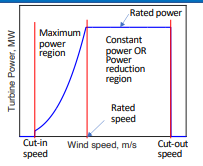

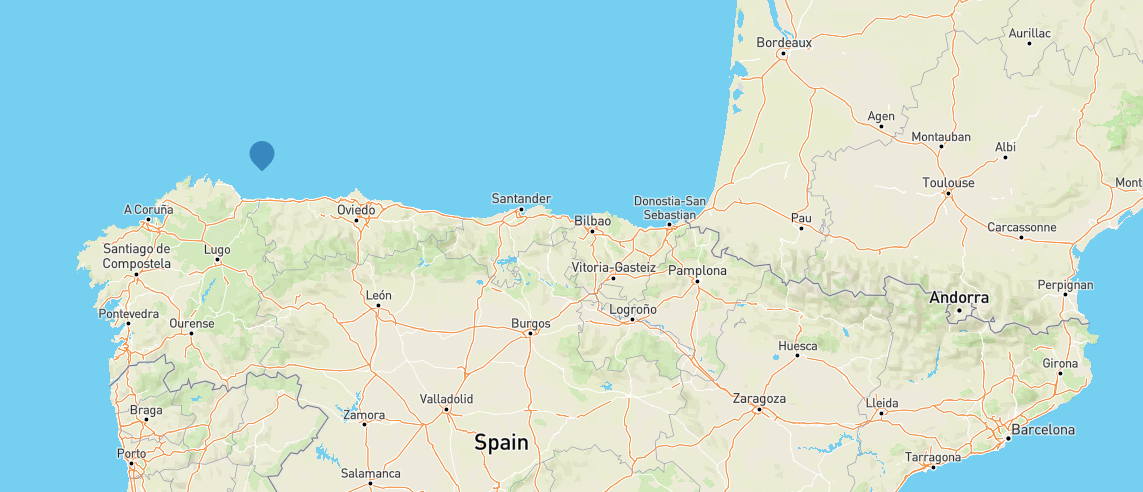

The wind turbine we will be analysing is found just off the north coast of Spain.

**Wind turbine parameters:**

- Cut-in speed: 3.1 m/s

- Cut-out speed: 22.5 m/s

- Rated speed: 9.6 m/s

- Rated Power: 8.5 MW

- Rotor Diameter: 203m

- Rotor Area: ${\left(\frac{203}{2}\right)}^2 \pi =32365\ldotp 47$

% define WT parameters
cutInSpeed = 3.1;
cutOutSpeed = 22.5;
ratedSpeed = 9.6;
ratedPower = 8.5e6;
Area = 32365.47;

To begin with we define the capacity factor as:


$$\textrm{capacity}\;\textrm{factor}=\frac{\textrm{actual}\;\textrm{energy}\;\textrm{output}\;\textrm{over}\;\mathrm{a}\;\textrm{period}}{\textrm{Maximum}\;\textrm{possible}\;\textrm{energy}\;\textrm{output}\;\textrm{over}\;\mathrm{a}\;\textrm{period}}$$


The maximum possible energy output is if the turbine is operating at the Rated power at all times, meaning that the maximum possible energy over a year is given by:


$$\textrm{Maximum}\;\textrm{possible}\;\textrm{energy}\;\textrm{output}\;\textrm{over}\;\mathrm{a}\;\textrm{year}=\textrm{Rated}\;\textrm{power}\times \textrm{time}$$


no_of_hours = length(wind_data);
max_energy = ratedPower*no_of_hours % max_energy = 74.46 GWh

max_energy = 7.4460e+10

As seen in the figure above, the actual energy output is composed of 4 (ideal) operation modes, the first is when wind speed is below the cut-in speed, at this point the turbine is not generating any power. The second is between the cut-in speed and the rated speed, where the turbine is operating at maximum power, and finally after the cut off speed, the turbine generates constant power at the rated power.

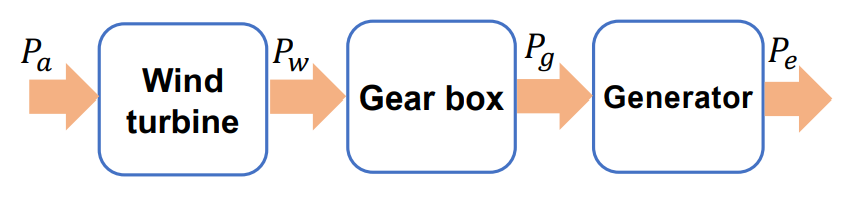

The actual power extracted $P_{e\;}$can be modelled in the pipeline above. $P_a$ refers to the availble wind power, and is determined by the rate of energy as a result of the flow of air through the area covered by the blades, and can be expressed as:


$$P_a =\frac{1}{2}\rho {\textrm{Av}}_w^3$$


Where $\rho$ is the air density as can be approximated as $1\ldotp 22\;{\;\textrm{kg}\cdot m}^{-3}$. $A$ refers to the area covered by the blades,  and $v_w$ is the wind speed. The extracted power is denoted


$$P_e =C_p \cdot \eta_{\textrm{gb}} \cdot \eta_{\textrm{ge}} \cdot P_a =k\cdot P_a$$


Where $\eta_{\textrm{gb}}$ is the gear box efficiency and $\eta_{\textrm{ge}}$ is the generator efficiency, and $C_p$ is the efficiency of power extraction from the wind, all of which are unknown to us and can be refered to as '$k$'. We know that there is no discontinuity at the rated speed interms of power generation, meaning that: $\frac{1}{2}\rho {\textrm{Av}}_{\textrm{rated}}^3 \cdot k=\textrm{rated}\;\textrm{power}\;\;\;\Rightarrow \;k=\frac{2\cdot \textrm{rated}\;\textrm{power}}{\rho {\textrm{Av}}_{\textrm{rated}}^3 }$

Using all the analysis above, a function for calculating energy generation over a period for given hourly wind data, cut-in speed, cut-out speed, rated power and blade area was written and can be found at the end of the file.

capacity_factor = energy_gen(wind_data, ratedPower, ratedSpeed, cutInSpeed, ...
                            cutOutSpeed, Area) ...
                            /max_energy;

The capacity factor is calculated to be 0.572, which is slightly high for typical capacity factors of off-shore wind turbines (usually between 0.4-0.5: https://www.iea.org/reports/offshore-wind-outlook-2019). This may be as a resut of some of the assumptions that have been made. The main assumption that does not hold true in practice, is that the turbine start-up is 100% efficient, i.e. the power generation is instantaneous when the turbine goes from the cut-in/cut-off speeds into the power generation regions. Another assumption is that the in the constant power region, the turbine is always generating at the maximum capicity, and can shut-off instaneously at the cut-off speed, when in fact the power generation drops off as the wind-speed approaches the cut-off speed (https://www.scirp.org/journal/paperinformation.aspx?paperid=75320).

## Question 2 - Wind speed pdf

The pdf of the wind speed follows a Weilbull distribution, given by:


$$pdf(v_w) = \frac{k}{A}\left(\frac{v_w}{A}\right)^{k-1}e^{\left(\frac{v_w}{A}\right)^{k}}$$


The weibull parameters can be estimated according to the wind speed data using MATLAB's  'wblfit' function. This is performed below, and plotted, along with it's corresponding histogram consisting of 30 bins.

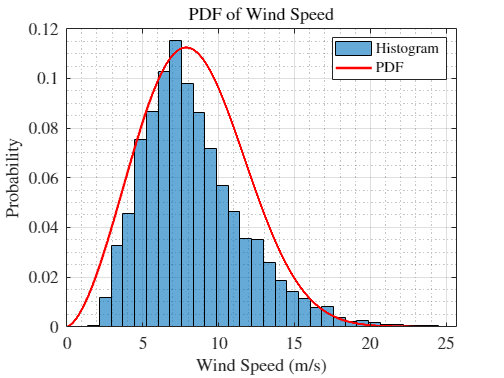

nbins = 30;
figure(1);
% estimate weibull parameters from data
p = wblfit(wind_data);
A = p(1); k = p(2);
max_wind_speed = max(wind_data, [], 'all');
x = linspace(0, max_wind_speed, 10000);
% Weibull pdf 
pdf = (k/A)*(x./A).^(k-1).*exp(-((x./A).^k));

figure(1);
h1 = histogram(wind_data, nbins,'Normalization','probability');
hold on
plot(x, pdf, 'r', 'LineWidth', 2);
set(gca, 'FontSize', 14)
xlabel('Wind Speed (m/s)')
ylabel('Probability')
title('PDF of Wind Speed')
legend('Histogram', 'PDF')
grid on;
grid minor;
hold off;


%finding most likely wind speed, i.e. the maximum of the pdf
[probability, index] = max(pdf);
ml_wind_speed = x(index); % ml_wind_speed = 7.8699 m/s

The number of hours that the most likely wind speed is encountered throughout the year is the probability of it occurring multiplied by the number of hours in a year, or in the case of the data, the length of the wind speed array.

ml_wind_hours = probability*length(wind_data); % ml_wind_hours = 985.267 hours

## Question 3 - Increasing rated capacity

The electrical component of the turbine are now retroffited to increase the rated capacity by 15% in yearly steps of 1%, we know aim to calculate and plot the change in annual energy output with respect to the percentage change. 

An increase in rated capacity essentially means that the value of '$k$',  the overall turbine efficiency, is increased yearly such that the rated power (8.5MW) at the rated speed, 9.6m/s, is increased by 1% each year. We get an array of the yearly rated powers and call the energy calculation function we have already written for each year.

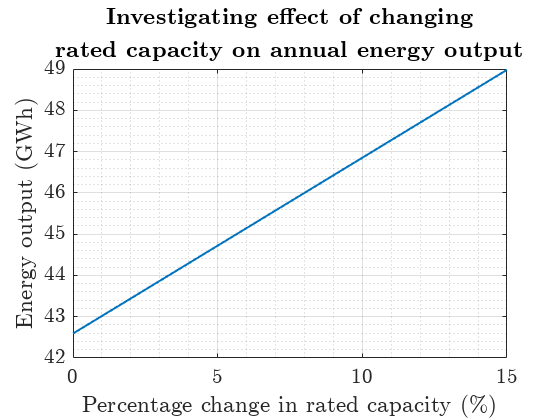

percentages = 0:1:15; % will be needed for plots
yearly_rated_powers = ratedPower:ratedPower*0.01:ratedPower*1.15
yearly_energy_output = zeros(1, length(yearly_rated_powers))

for i = 1:length(yearly_energy_output)
    yearly_energy_output(i) = energy_gen(wind_data, yearly_rated_powers(i), ...
                                         ratedSpeed, cutInSpeed, cutOutSpeed, Area)
end
figure(2);
plot(percentages, yearly_energy_output./10^9, LineWidth=1.5)
set(gca, 'FontSize', 16)
ylabel("Energy output (GWh)")
xlabel("Percentage change in rated capacity (\%)")
title("\textbf{Investigating effect of changing}","\textbf{rated capacity " + ...
    "on annual energy output}")
grid on; grid minor; hold off;

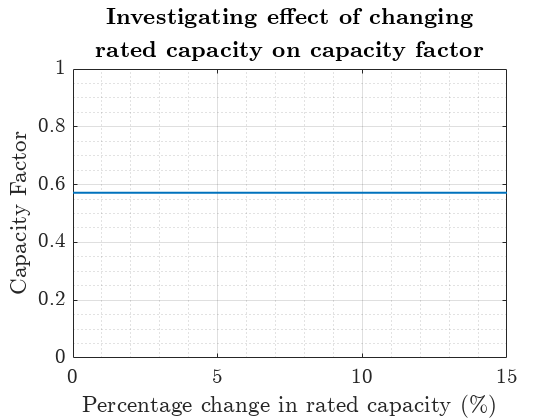

figure(3);
% Now plotting rated capacity using the same formula as before
plot(percentages, yearly_energy_output./(length(wind_data)*yearly_rated_powers) ...
     , LineWidth=1.5)
ylabel("Capacity Factor")
set(gca, 'FontSize', 16)
ylim([0 1])
xlabel("Percentage change in rated capacity (\%)")
title("\textbf{Investigating effect of changing}", ...
    "\textbf{rated capacity on capacity factor}")
grid on; grid minor; hold off;

## Question 4 -  Evaluation

The relationship between percentage change in rated capacity and  annual energy output is linear,  this means that there is no particular nuance to upgrading components in terms of energy generation. As a result, the only factor that needs to be considered is the economic impact of upgrade costs as electrical components become more and more efficient (this is likely not to be a linear relationship). Despite the increase in total energy generation, the maximum possible energy generation is also linearly increased by the same factor, meaning that for the same wind speeds, the capacity factor remains constant despite the increase in rated capacity, as seen in the above figure.  There are a series of assumptions made that meant that the relationship between the change in rated capacity and the Energy output were linear. The first is that the turbine start-up is completely efficient, i.e. at the start-up speed the turbine instantaneously starts generating $\frac{1}{2}k\cdot \rho {\textrm{Av}}_{\textrm{start}-\textrm{up}}^3$ watts, where in fact this is not instaneous, and is likely to be longer for a larger value of $k$ (higher rated capacity) which must reacher higher power generation upon start up. This assumption also applies to the transition from the cut-out speed to the constant power region, and the transition from the maximum-power region to the constant-power region. Another assumption is that the turbine is always generating at the rated power in the constant power region, this however, as seen in the figure below, is not the case, and thus the power generated when in this region will likely be much lower. The resulting estimated capacity factor is thus much higher than typical values for off-shore wind turbines (capacity factor usually between 0.4-0.5).

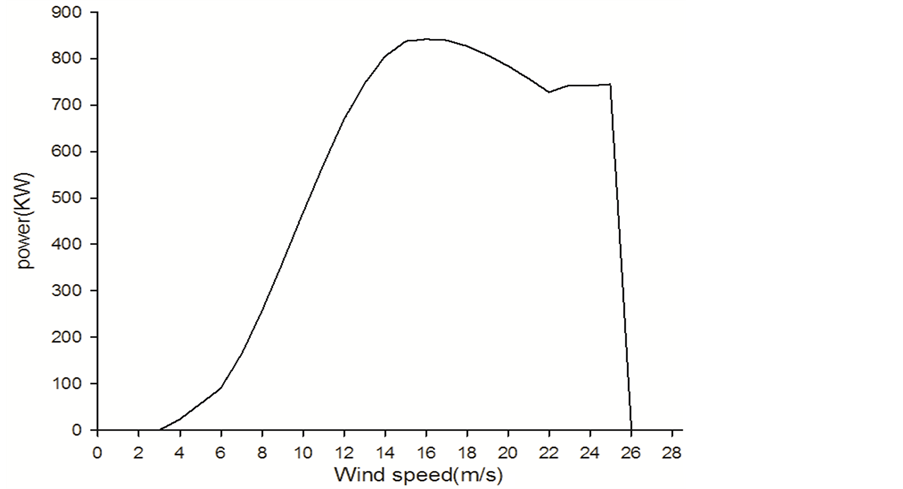

***Figure: Wind power curve of Nordex N50/800 (https://www.scirp.org/journal/paperinformation.aspx?paperid=75320).***

Our allocated wind turbine is in a relatively high-wind speed location, especially in comparison with on-shore wind farms (see the figure below), hence the high capacity factor. 

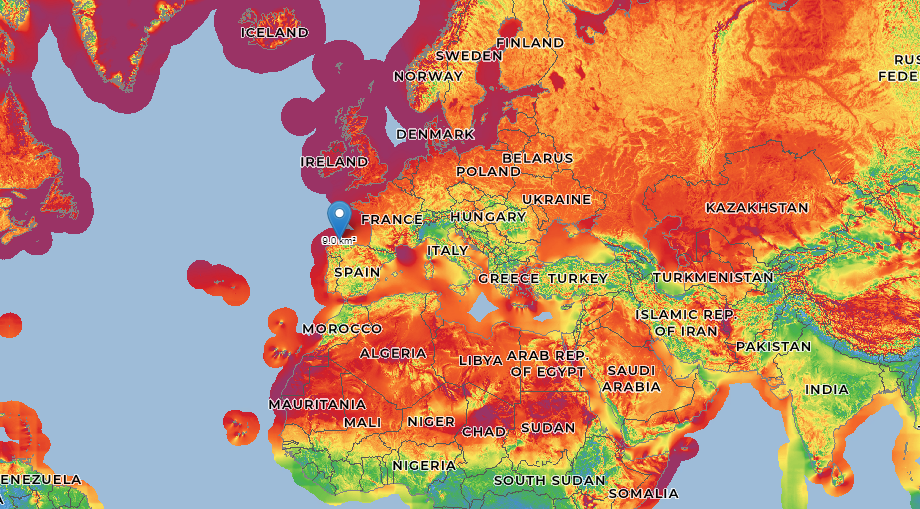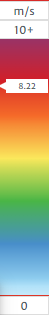

***Figure: Mean wind speeds around the world (source: ***globalwindatlas.info).

## Energy generation calculation function

function generated_energy = energy_gen(wind_data, ratedPower, ratedSpeed, cutInSpeed, ...
                                       cutOutSpeed, Area)
    rho = 1.22; % air density
    k = 2*ratedPower/(rho*Area*(ratedSpeed^3)); % efficiency factor

    % find wind speeds where WT is not generating
    zeroPowerSpeeds = wind_data < cutInSpeed | wind_data > cutOutSpeed;
    wind_with_power = wind_data(~zeroPowerSpeeds);
    % find speeds where we are in the contant power and maximum power regions
    constPowerSpeedsidx = wind_with_power > ratedSpeed;
    
    const_power_speeds = wind_with_power(constPowerSpeedsidx);
    maximum_power_speeds = wind_with_power(~constPowerSpeedsidx);
    %find power generated at each hour for given wind speed below rated speed
    max_power = ((maximum_power_speeds).^3).*(0.5*rho*Area*k); 
    %number of hours at rated speed times by rated power
    const_energy_tot = length(const_power_speeds)*ratedPower; 

    generated_energy = sum(max_power) + const_energy_tot;
end